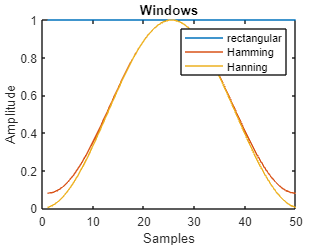

%problem1 part 1
L0=50;
x1=rectwin(L0);
plot(x1)
hold on
title('rectangular window');
xlabel('samples');
ylabel('amplitude');
x2 = hamming(L0);
plot(x2)
title('hamming window');
xlabel('samples');
ylabel('amplitude')
x3 = hanning(L0);
plot(x3)
title('hanning window');
xlabel('samples');
ylabel('amplitude')
title("Windows")
xlabel("Samples")
ylabel("Amplitude")
legend("rectangular","Hamming","Hanning")
hold off

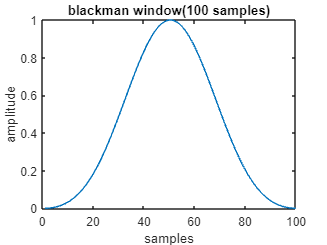


%problem 1 part 2
alpha=1+mod(163,3);
L1=100;
L2=200;
b1=blackman(100);
plot(b1)
title('blackman window(100 samples)');
xlabel('samples');
ylabel('amplitude')

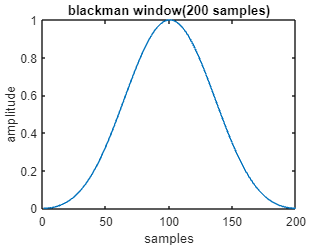

b2=blackman(200);
plot(b2)
title('blackman window(200 samples)');
xlabel('samples');
ylabel('amplitude')

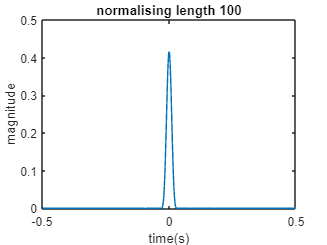

Fs = 1000;                              
T = 1/Fs;                    
L = 1024;             
t = (-L/2:L/2-1)./L;
%normalising length=100
B1=blackman(L1);
y1=abs(fftshift(fft(B1,1024)))/100;      
plot(t,y1)
xlabel('time(s)');
ylabel('magnitude');
title('normalising length 100');

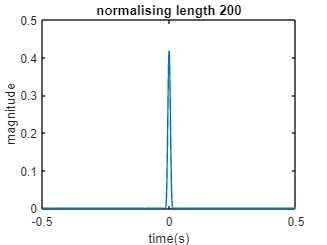

%normalising length=200
B2=blackman(L2);
y2=abs(fftshift(fft(B2,1024)))/200;
plot(t,y2)
xlabel('time(s)');
ylabel('magnitude');
title('normalising length 200');

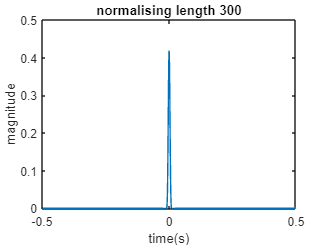

%normalising length 300
L3=300;
B3=blackman(L3);
y3=abs(fftshift(fft(B3,1024)))/300;
plot(t,y3)
xlabel('time(s)');
ylabel('magnitude');
title('normalising length 300');

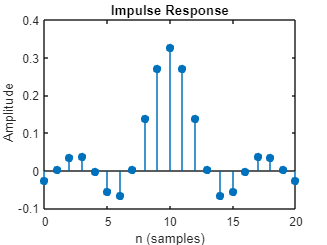


%question 2 
w1=rectwin(21);
a=fir1(20,0.33,'low',w1);
impz(a)

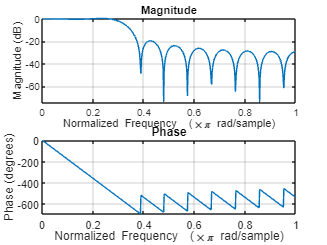

freqz(a)

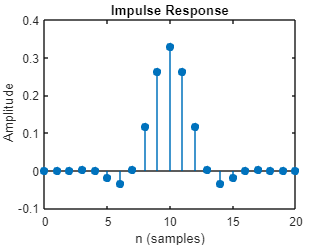


w2=blackman(21);
a1=fir1(20,0.33,'low',w2);
impz(a1)

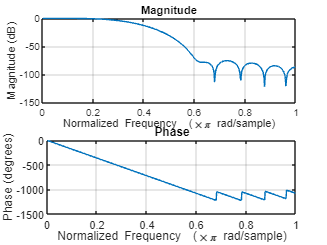

freqz(a1)

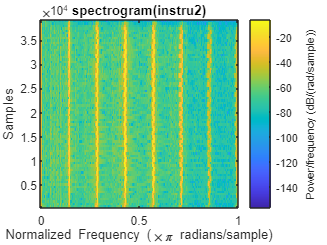


%problem 3
[y,Fs1]=audioread("C:\Users\vishn\OneDrive\Desktop\instru2.wav");
N=1000;
spectrogram(y,hamming(N))
title('spectrogram(instru2)');

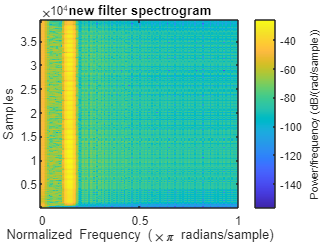

B4=fir1(99,1800/Fs1,'low',hamming(100));
y4=filter(B4,2,y);
spectrogram(y4,hamming(100))
title('new filter spectrogram');

audiowrite('writtenfile.wav',y4,Fs1);
[y5,Fs2]=audioread('writtenfile.wav');
sound(y5,Fs2)

